[x, fs] = audioread("E:\学\大二上\信号\lab\lab5\C_01_01(1).wav");

% a
% Concatenate 10 speech waveforms into one signal
sig = repmat(x, 10, 1);

% 功率谱密度
[pxx, w] = periodogram(sig, [], 512, fs); % (x,window,f频率,fs) w：ω取值

% b
% 得到滤波器系数
b = fir2(3000, w/(fs/2), sqrt(pxx/max(pxx))); % 将所需的频率响应线性插值到密集的网格上，然后使用傅立叶逆变换和 Hamming 窗来获得滤波器系数。(n,f,m) n: Filter order f:指定频率点的幅度响应样本 m:幅度响应样本
[h, wh] = freqz(b, 1, 128); % (b,a,n) n: 估计的点的数量 h：频率响应 w：ω

% c
% 生成白噪声
noise = 1 - 2 * randn(length(sig), 1);

% d
% 对噪声信号滤波
y = filter(b, 1, noise);
[pxx_y, w_y] = periodogram(y, [], 512, fs);

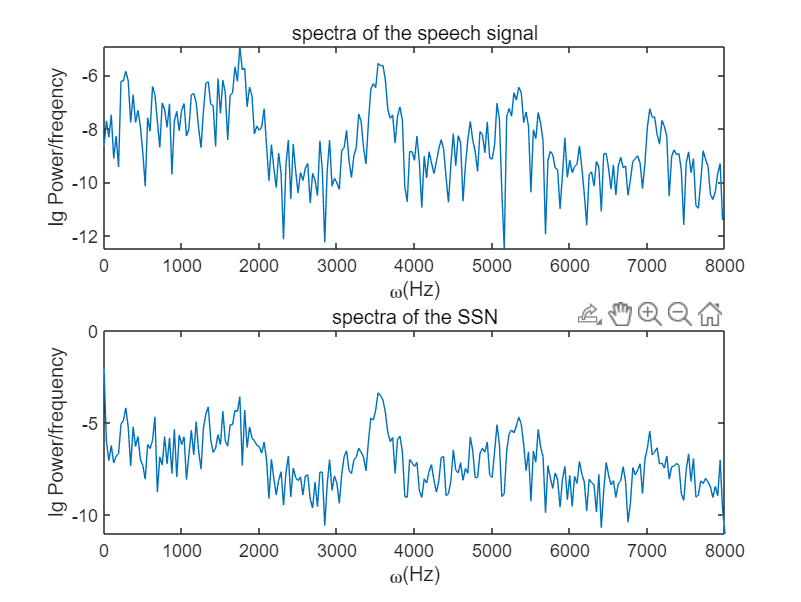

subplot(2, 1, 1);
plot(w, log10(pxx));
xlabel("\omega(Hz)");
ylabel("lg Power/freqency");
title("spectra of the speech signal");

subplot(2, 1, 2);
plot(w_y, log10(pxx_y));
xlabel("\omega(Hz)");
ylabel("lg Power/frequency");
title("spectra of the SSN");

audiowrite("E:\学\大二上\信号\lab\lab5\SSN.wav", y, fs);